# DWSIM Surrogate Model-Based Optimization

## Goals

- Demonstrate a quick and flexible optimization framework using DWSIM models and their surrogates.

## High-Level Highlights

The surrogate model-based optimization framework leverages the speed and structure of surrogate models to provide quick and robust solutions to engineering optimization problems. We demonstrate this framework in the context of DWSIM models. The image below shows a typical result from the examples presented below. The surrogate model-based optimization can produce results in seconds (4.14 seconds), while a physics-based approach would take orders of magnitude more time (8416.99 seconds). 

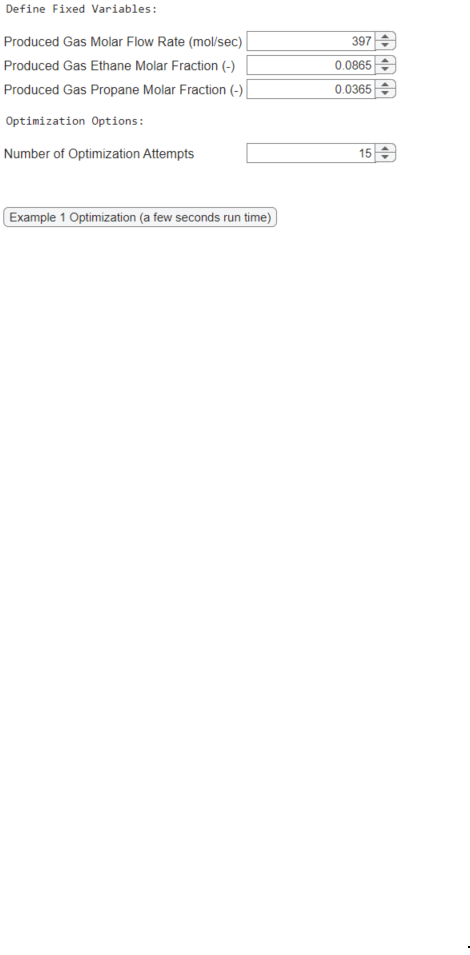

## Surrogate Model-Based Optimization 

In Surrogate Model-Based Optimization, we introduced an optimization framework that leverages the speed and flexibility of surrogate models to accelerate workflows. We demonstrated that the surrogate-based approach can solve constrained optimization problems in a fraction of the time compared to what a physics-based framework would require. This framework was the underlying engine that made computationally expensive workflows presented in Parameter Estimation via Profile Likelihoods and Anomaly Detection feasible. In the examples below, we again demonstrate the strengths of this framework through a series of optimization examples of a natural gas processing plant. 

### Surrogate Model

We refer the reader to DWSIM Surrogate Creation for a complete discussion of the natural gas processing surrogate model used here. The surrogate model's inputs, outputs, and accuracy are all tabulated there. 

## Examples

The optimization examples focus on a DWSIM [1] model of a natural gas processing plant, aiming to minimize energy consumption while meeting defined constraints. Though simplified, these examples effectively demonstrate the framework's ability to optimize objectives that depend on multiple model outputs.

To simplify the examples, we assume energy usage is computed directly from the duties of different equipment and is simply a sum of the duties. In reality, energy usage will depend on various factors, such as equipment efficiency. However, the examples demonstrate the surrogate model-based optimization framework can minimize an objective that is a function of several of the model's outputs. The table below lists mechanical equipment included in the energy usage equation.  

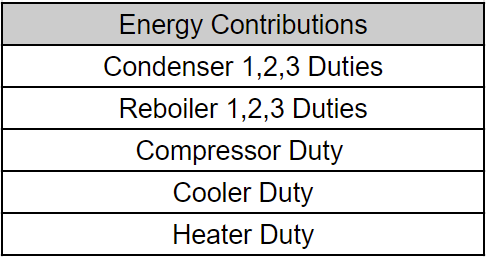

We define constraints on the compositions of bottom streams for all three distillation columns. To simplify these examples, we defined only constraints on the amount of light key in the bottom material streams. However, constraints can be tailored to accommodate more intricate industry specifications. The constraints ensure only a small amount of the light key ends up in the bottom streams. The table below shows the constraints used in Examples 1 and 2. Example 3 allows the user to customize the constraints directly.  

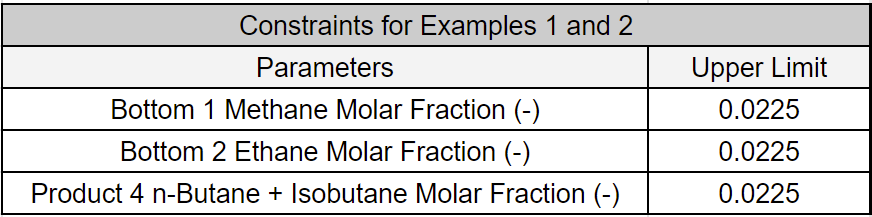

Users also have the flexibility to adjust the composition of the produced gas (the incoming gas into the system). As discussed in DWSIM Surrogate Creation, methane, ethane, and propane molar fractions of the produced gas are inputs to the surrogate model. However, each of these inputs has upper and lower bounds, and, in addition, the sum of these molar fractions must equal 0.8376 (to ensure a well-defined composition). Therefore, in the examples below, the user can adjust ethane and propane molar fractions while the methane molar fraction is computed based on the summation constraint ($\text{x}_\text{methane} = 0.8376 - \text{x}_\text{ethane} - \text{x}_\text{propane}$).   

The image below displays a labeled flow sheet of the natural gas processing plant. 

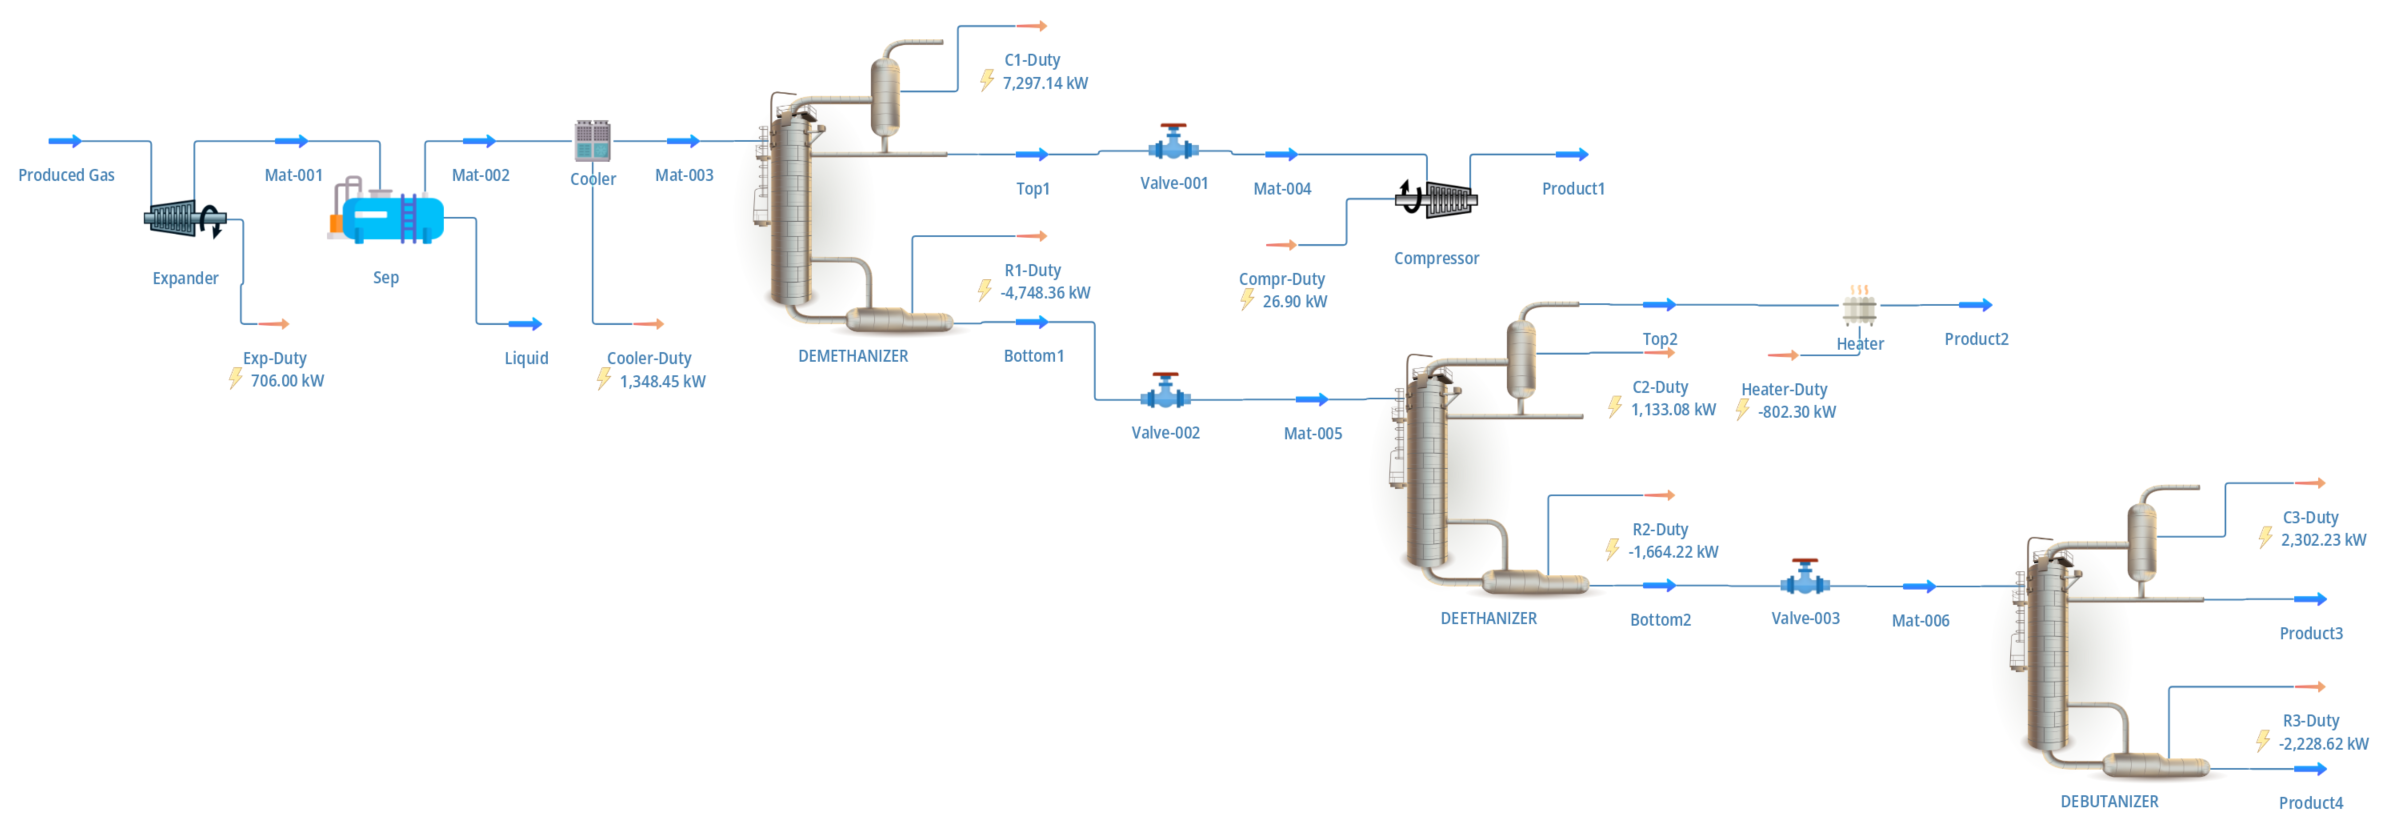

### Example 1: Minimize Energy Usage 

This example aims to determine the optimal operational settings that minimize energy usage while satisfying production constraints. The problem statement is summarized below:


$$$\text{minimize Energy Usage } \\  \text{subject to} \\ \text{Bottom1}_{\text{methane}}\leq0.025, \\ \text{Bottom1}_{\text{ethane}}\leq0.025, \\ \text{Product4}_{\text{butanes}}\leq0.025.$$$$


The table below lists the decision and fixed variables of this optimization problem. For a discussion of the differences between decision and fixed variables, refer to Surrogate Model-Based Optimization. 

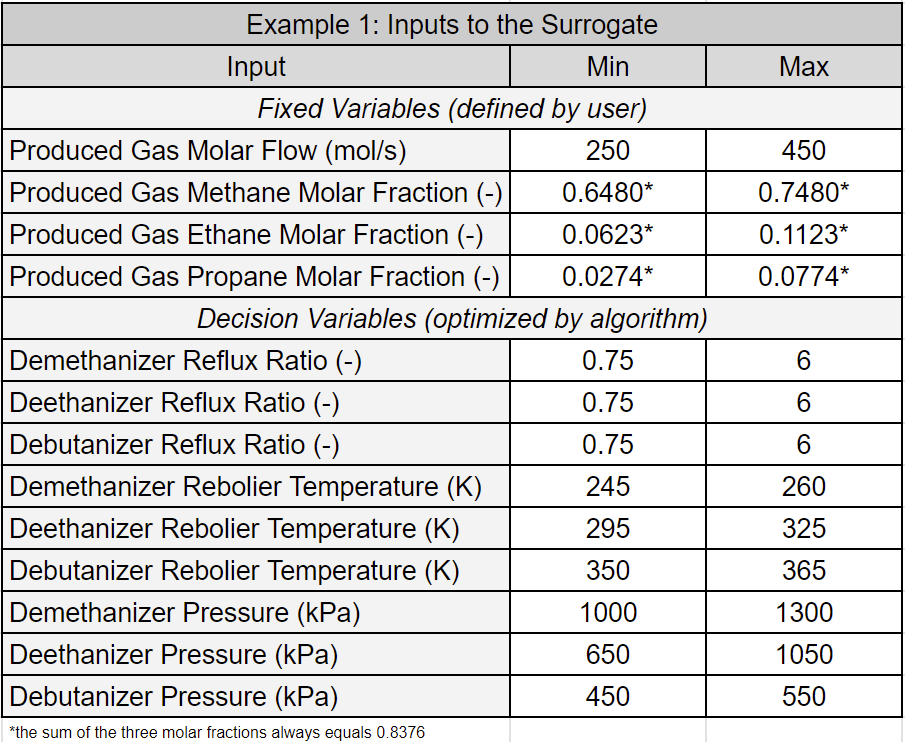

Within the GUI interface, users can adjust fixed variables and choose the number of optimization attempts. After setting these parameters, they can initiate the optimization algorithm by clicking the designated button.

The optimization process outputs a computational speed comparison between the surrogate model-based and physics-based approaches. It's important to note the significant differences in computational time. The surrogate model-based optimization can produce results in seconds, while the physics-based approach would take orders of magnitude more time. To ensure a fair comparison, we assume the physics-based approach will need the same amount of function evaluations. Furthermore, we use the average DWSIM execution time of the collected samples used for surrogate training.

disp("Define Fixed Variables:")

Define Fixed Variables:


producedGasMolarflow = 397;
producedGasEthaneFrac = 0.0865;
producedGasPropaneFrac = 0.0365;
producedGasMethaneFrac = 0.8376 - producedGasEthaneFrac - producedGasPropaneFrac;
systemParameter.producedGasMolarflow = producedGasMolarflow; % [250,450]
systemParameter.producedGasEthane = producedGasEthaneFrac; %[0.0623,0.1123];
systemParameter.producedGasPropane = producedGasPropaneFrac; %[0.0274,0.0774];
systemParameter.producedGasMethane = producedGasMethaneFrac;
disp("Optimization Options:")

Optimization Options:


numAttempts = 15;
disp(" ")

 

addpath("Surrogate Model\")
addpath("Optimization\")
addpath("Model\")

tic
[xOpt, energyExpense,constraints,funEvals,exitFlag] = example1_optimization(systemParameter, round(numAttempts));
timeElasped = toc;

if exitFlag
    disp(" ")
    disp("Fixed Variables:")
    disp(['Produced Gas Molar Flow (mol/sec): ' num2str(producedGasMolarflow,'%.0f')])
    disp(['Ethane Molar Fraction (-): ' num2str(producedGasEthaneFrac,'%.2f')])
    disp(['Propane Molar Fraction (-): ' num2str(producedGasPropaneFrac,'%.2f')])
    disp(['Methane Molar Fraction (-): ' num2str(producedGasMethaneFrac,'%.2f')])
    disp(" ")
    disp(['Optimal Total Energy Usage (kW): ' num2str(energyExpense(1),'%.2f')])
    disp(['Condenser 1 Duty (kW): ' num2str(energyExpense(2),'%.2f')])
    disp(['Condenser 2 Duty (kW): ' num2str(energyExpense(3),'%.2f')])
    disp(['Condenser 3 Duty (kW): ' num2str(energyExpense(4),'%.2f')])
    disp(['Reboiler 1 Duty (kW): ' num2str(energyExpense(5),'%.2f')])
    disp(['Reboiler 1 Duty (kW): ' num2str(energyExpense(6),'%.2f')])
    disp(['Reboiler 1 Duty (kW): ' num2str(energyExpense(7),'%.2f')])
    disp(['Compressor Duty (kW): ' num2str(energyExpense(8),'%.2f')])
    disp(['Cooler Duty (kW): ' num2str(energyExpense(9),'%.2f')])
    disp(['Heater Duty (kW): ' num2str(energyExpense(10),'%.2f')])
    disp(" ")
    disp("Optimal Operational Settings:")
    disp(['Demethanizer Reflux Ratio (-): ' num2str(xOpt(1),'%.2f')])
    disp(['Deethanizer Reflux Ratio (-): ' num2str(xOpt(2),'%.2f')])
    disp(['Debutanizer Reflux Ratio (-): ' num2str(xOpt(3),'%.2f')])
    disp(['Demethanizer Reboiler Temperature (K): ' num2str(xOpt(4),'%.2f')])
    disp(['Deethanizer Reboiler Temperature (K): ' num2str(xOpt(5),'%.2f')])
    disp(['Debutanizer Reboiler Temperature (K): ' num2str(xOpt(6),'%.2f')])
    disp(['Demethanizer Top_pressure (kPa): ' num2str(xOpt(7)/1000,'%.0f')])
    disp(['Deethanizer  Top_pressure (kPa): ' num2str(xOpt(8)/1000,'%.0f')])
    disp(['Debutanizer  Top_pressure (kPa): ' num2str(xOpt(9)/1000,'%.0f')])
    disp(" ")
    disp("Constraints:")
    disp(['Bottom 1 Methane Molar Fraction (-): ' num2str(constraints(1),'%.4f')])
    disp(['Bottom 2 Ethane Molar Fraction (-): ' num2str(constraints(2),'%.4f')])
    disp(['Product 4 n-Butane + Isobutane Molar Fraction (-): ' num2str(constraints(3),'%.4f')])
    disp(" ")
    disp("Optimization Performance:")
    disp(['Number of Optimization Attempts: ' num2str(round(numAttempts))])
    disp(['Total Number of Function Evaluations: ' num2str(funEvals)])
    disp(['Total Surrogate Model-Based Optimization Time (sec): ' num2str(timeElasped,'%.2f')])
    disp(['Predicted Total Physics-Based Optimization Time (sec): ' num2str(funEvals*4.9570,'%.2f')])
else
    disp("Error with optimization! Retry")
end

Fixed Variables:


Produced Gas Molar Flow (mol/sec): 397


Ethane Molar Fraction (-): 0.09


Propane Molar Fraction (-): 0.04


Methane Molar Fraction (-): 0.71


Optimal Total Energy Usage (kW): 9714.91


Condenser 1 Duty (kW): 3729.10


Condenser 2 Duty (kW): 318.97


Condenser 3 Duty (kW): 970.67


Reboiler 1 Duty (kW): 604.54


Reboiler 1 Duty (kW): 928.41


Reboiler 1 Duty (kW): 922.54


Compressor Duty (kW): 27.93


Cooler Duty (kW): 1315.28


Heater Duty (kW): 897.46


Optimal Operational Settings:


Demethanizer Reflux Ratio (-): 0.75


Deethanizer Reflux Ratio (-): 0.75


Debutanizer Reflux Ratio (-): 0.75


Demethanizer Reboiler Temperature (K): 252.22


Deethanizer Reboiler Temperature (K): 308.15


Debutanizer Reboiler Temperature (K): 362.32


Demethanizer Top_pressure (kPa): 1000


Deethanizer  Top_pressure (kPa): 778


Debutanizer  Top_pressure (kPa): 522


Constraints:


Bottom 1 Methane Molar Fraction (-): 0.0174


Bottom 2 Ethane Molar Fraction (-): 0.0172


Product 4 n-Butane + Isobutane Molar Fraction (-): 0.0184


Optimization Performance:


Number of Optimization Attempts: 15


Total Number of Function Evaluations: 1513


Total Surrogate Model-Based Optimization Time (sec): 3.83


Predicted Total Physics-Based Optimization Time (sec): 7499.94


The speed of the surrogate model-based optimization framework enhances existing workflows, offering users deeper insights into system performance. For instance, it can swiftly generate optimization curves, providing operators with a comprehensive view of optimal system behavior.

The GUI below efficiently computes the optimal operational settings and energy usage over a range of produced gas flow rates (while keeping the compositional fractions static). We can create the plot using a surrogate model-based framework in less than a minute. In contrast, a physics-based optimization framework would require extensive computational resources and time to achieve comparable results.

disp("Define Fixed Variables:")

Define Fixed Variables:


producedGasEthaneFrac = 0.0865;
producedGasPropaneFrac = 0.0365;
producedGasMethaneFrac = 0.8376 - producedGasEthaneFrac - producedGasPropaneFrac;

systemParameter.producedGasEthane = producedGasEthaneFrac; %[0.0623,0.1123];
systemParameter.producedGasPropane = producedGasPropaneFrac; %[0.0274,0.0774];
systemParameter.producedGasMethane = producedGasMethaneFrac;
disp("Optimization Options:")

Optimization Options:


numAttempts = 10;
disp(" ")

 

tic
energyExp = zeros(1,9);
molarFlows = [250,275,300,325,350,375,400,425,450];
for idx = 1:numel(molarFlows)
    systemParameter.producedGasMolarflow = molarFlows(idx); % [250,450]
    [~,energyExpense,~,~,~] = example1_optimization(systemParameter, round(numAttempts));
    energyExp(idx) = energyExpense(1);
end
timeElasped = toc;

disp(" ")

disp("Fixed Variables:")

Fixed Variables:


disp(['Produced Gas Molar Flow (mol/sec): ' num2str(producedGasMolarflow,'%.0f')])

Produced Gas Molar Flow (mol/sec): 397


disp(['Ethane Molar Fraction (-): ' num2str(producedGasEthaneFrac,'%.2f')])

Ethane Molar Fraction (-): 0.09


disp(['Propane Molar Fraction (-): ' num2str(producedGasPropaneFrac,'%.2f')])

Propane Molar Fraction (-): 0.04


disp(['Methane Molar Fraction (-): ' num2str(producedGasMethaneFrac,'%.2f')])

Methane Molar Fraction (-): 0.71


disp(" ")

disp(['Optimization Time (sec), 9 different flowrates: ' num2str(timeElasped,'%.2f')])

Optimization Time (sec), 9 different flowrates: 25.27


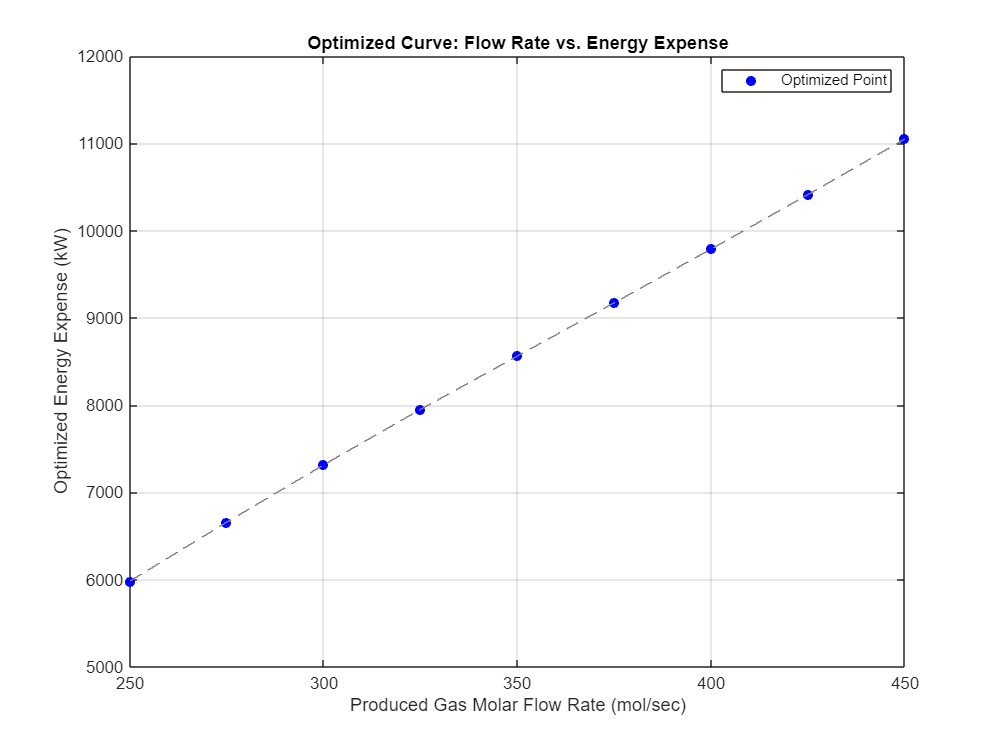


figure('Position', [100, 100, 800, 600])
hold on
scatter(molarFlows,energyExp,'b','filled')  
plot(molarFlows,energyExp,'--', 'color', [0.5, 0.5, 0.5, 0.5])   
title('Optimized Curve: Flow Rate vs. Energy Expense')
ylabel('Optimized Energy Expense (kW)')
xlabel('Produced Gas Molar Flow Rate (mol/sec)')
legend('Optimized Point')
box on 
grid on

### Example 2: Target Product 1 Flowrate

As in Example 1, this example aims to determine the optimal operational settings that minimize energy usage while satisfying production constraints. In addition to these constraints, the user defines a desired flow rate, $$FR_1$$, for Product 1. The statement below summarizes the optimization problem: 


$$$\text{minimize Energy Usage } \\  \text{subject to} \\ \text{Product1 Flowrate}\approx FR_1,  \\ \text{Bottom1}_{\text{methane}}\leq0.025, \\ \text{Bottom1}_{\text{ethane}}\leq0.025, \\ \text{Product4}_{\text{butanes}}\leq0.025.$$$$


The table below lists the decision and fixed variables of this optimization problem. Unlike Example 1, the flow rate of produced gas is now a decision variable. For a discussion of the differences between decision and fixed variables, refer to Surrogate Model-Based Optimization. 

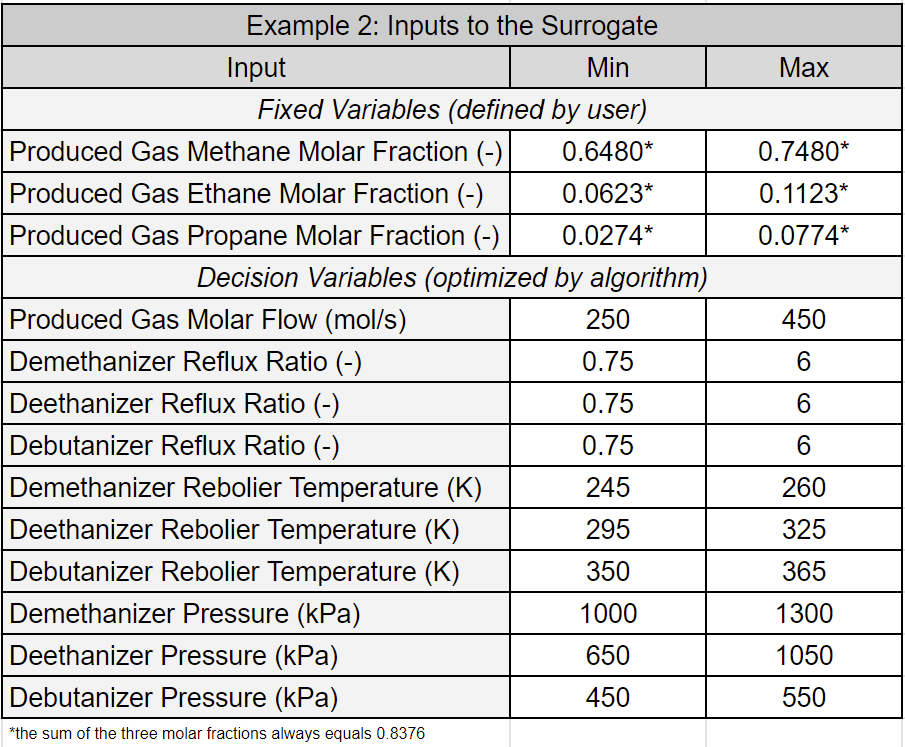

Within the GUI interface, users can adjust fixed variables and choose the number of optimization attempts. After setting these parameters, they can initiate the optimization algorithm by clicking the designated button.

Note that the optimization framework successfully determined operational settings that achieve the desired Product 1 flow rate (within a small tolerance) while minimizing energy usage. Furthermore, similar to Example 1, the surrogate model-based optimization framework performs significantly faster than its physics-based counterpart.

disp("Define Fixed Variables:")

Define Fixed Variables:


targetProduct1MolarFlow = 213;
producedGasEthaneFrac = 0.105;
producedGasPropaneFrac = 0.036;
producedGasMethaneFrac = 0.8376 - producedGasEthaneFrac - producedGasPropaneFrac;

systemParameter.producedGasEthane = producedGasEthaneFrac; %[0.0623,0.1123];
systemParameter.producedGasPropane = producedGasPropaneFrac; %[0.0274,0.0774];
systemParameter.producedGasMethane = producedGasMethaneFrac;
disp("Optimization Options:")

Optimization Options:


numAttempts = 10;
disp(" ")

 

addpath("Surrogate Model\")
addpath("Optimization\")
addpath("Model\")

tic
[xOpt, energyExpense,constraints,product1FlowRate,funEvals,exitFlag,successes] = example2_optimization(systemParameter, round(numAttempts),targetProduct1MolarFlow);
timeElasped = toc;

if exitFlag
    disp("Fixed Variables:")
    disp(['Ethane Molar Fraction (-): ' num2str(producedGasEthaneFrac)])
    disp(['Propane Molar Fraction (-): ' num2str(producedGasPropaneFrac)])
    disp(['Methane Molar Fraction (-): ' num2str(producedGasMethaneFrac)])
    disp(" ")
    disp(['Optimal Total Energy Usage (kW): ' num2str(energyExpense(1),'%.2f')])
    disp(['Condenser 1 Duty (kW): ' num2str(energyExpense(2),'%.2f')])
    disp(['Condenser 2 Duty (kW): ' num2str(energyExpense(3),'%.2f')])
    disp(['Condenser 3 Duty (kW): ' num2str(energyExpense(4),'%.2f')])
    disp(['Reboiler 1 Duty (kW): ' num2str(energyExpense(5),'%.2f')])
    disp(['Reboiler 1 Duty (kW): ' num2str(energyExpense(6),'%.2f')])
    disp(['Reboiler 1 Duty (kW): ' num2str(energyExpense(7),'%.2f')])
    disp(['Compressor Duty (kW): ' num2str(energyExpense(8),'%.2f')])
    disp(['Cooler Duty (kW): ' num2str(energyExpense(9),'%.2f')])
    disp(['Heater Duty (kW): ' num2str(energyExpense(10),'%.2f')])
    disp(" ")
    disp("Optimal Operational Settings:")
    disp(['Produced Gas Molar Flow Rate (mol/sec): ' num2str(xOpt(1),'%.2f')])
    disp(['Demethanizer Reflux Ratio (-): ' num2str(xOpt(2),'%.2f')])
    disp(['Deethanizer Reflux Ratio (-): ' num2str(xOpt(3),'%.2f')])
    disp(['Debutanizer Reflux Ratio (-): ' num2str(xOpt(4),'%.2f')])
    disp(['Demethanizer Reboiler Temperature (K): ' num2str(xOpt(5),'%.2f')])
    disp(['Deethanizer Reboiler Temperature (K): ' num2str(xOpt(6),'%.2f')])
    disp(['Debutanizer Reboiler Temperature (K): ' num2str(xOpt(7),'%.2f')])
    disp(['Demethanizer Top_pressure (kPa): ' num2str(xOpt(8)/1000,'%.0f')])
    disp(['Deethanizer  Top_pressure (kPa): ' num2str(xOpt(9)/1000,'%.0f')])
    disp(['Debutanizer  Top_pressure (kPa): ' num2str(xOpt(10)/1000,'%.0f')])
    disp(" ")
    disp("Constraints:")
    disp(['Bottom 1 Methane Molar Fraction (-): ' num2str(constraints(1),'%.4f')])
    disp(['Bottom 2 Ethane Molar Fraction (-): ' num2str(constraints(2),'%.4f')])
    disp(['Product 4 n-Butane + Isobutane Molar Fraction (-): ' num2str(constraints(3),'%.4f')])
    disp(" ")
    disp("Target Flowrates:")
    disp(['Target Product 1 Molar Flowrate (mol/sec): ' num2str(targetProduct1MolarFlow,'%.2f')])
    disp(['Predicted Product 1 Molar Flowrate (mol/sec): ' num2str(product1FlowRate,'%.2f')])
    disp(" ")
    disp("Optimization Performance:")
    disp(['Number of Optimization Attempts: ' num2str(round(numAttempts))])
    disp(['Total Number of Function Evaluations: ' num2str(funEvals)])
    disp(['Total Surrogate Model-Based Optimization Time (sec): ' num2str(timeElasped,'%.2f')])
    disp(['Predicted Total Physics-Based Optimization Time (sec): ' num2str(funEvals*4.9570,'%.2f')])
else
    disp("Error with optimization! Retry")
end

Fixed Variables:


Ethane Molar Fraction (-): 0.105


Propane Molar Fraction (-): 0.036


Methane Molar Fraction (-): 0.6966


Optimal Total Energy Usage (kW): 6873.00


Condenser 1 Duty (kW): 2505.47


Condenser 2 Duty (kW): 239.78


Condenser 3 Duty (kW): 699.95


Reboiler 1 Duty (kW): 302.72


Reboiler 1 Duty (kW): 808.44


Reboiler 1 Duty (kW): 595.48


Compressor Duty (kW): 19.07


Cooler Duty (kW): 938.61


Heater Duty (kW): 763.49


Optimal Operational Settings:


Produced Gas Molar Flow Rate (mol/sec): 275.98


Demethanizer Reflux Ratio (-): 0.75


Deethanizer Reflux Ratio (-): 0.75


Debutanizer Reflux Ratio (-): 0.75


Demethanizer Reboiler Temperature (K): 249.82


Deethanizer Reboiler Temperature (K): 321.63


Debutanizer Reboiler Temperature (K): 356.13


Demethanizer Top_pressure (kPa): 1000


Deethanizer  Top_pressure (kPa): 1050


Debutanizer  Top_pressure (kPa): 450


Constraints:


Bottom 1 Methane Molar Fraction (-): 0.0176


Bottom 2 Ethane Molar Fraction (-): 0.0150


Product 4 n-Butane + Isobutane Molar Fraction (-): 0.0172


Target Flowrates:


Target Product 1 Molar Flowrate (mol/sec): 213.00


Predicted Product 1 Molar Flowrate (mol/sec): 212.55


Optimization Performance:


Number of Optimization Attempts: 10


Total Number of Function Evaluations: 3080


Total Surrogate Model-Based Optimization Time (sec): 7.29


Predicted Total Physics-Based Optimization Time (sec): 15267.56


Similar to Example 1, the surrogate model-based optimization framework enhances understanding of system behavior by leveraging its speed. The GUI below calculates optimal produced gas flow rates and energy usage across a range of desired flow rates for Product 1 (while keeping the compositional fractions static).   

disp("Define Fixed Variables:")

Define Fixed Variables:


producedGasEthaneFrac = 0.08;
producedGasPropaneFrac = 0.036;
producedGasMethaneFrac = 0.8376 - producedGasEthaneFrac - producedGasPropaneFrac;

systemParameter.producedGasEthane = producedGasEthaneFrac; %[0.0623,0.1123];
systemParameter.producedGasPropane = producedGasPropaneFrac; %[0.0274,0.0774];
systemParameter.producedGasMethane = producedGasMethaneFrac;
disp("Optimization Options:")

Optimization Options:


numAttempts = 15;
disp(" ")

 

tic
energyExp = zeros(1,11);
proGasRate = zeros(1,11);
product1Flows = [200,205,210,215,220,225,230,235,240,245,250];
for idx = 1:numel(product1Flows)
    targetProduct1MolarFlow = product1Flows(idx); % [250,450]
    [xOpt, energyExpense,~,~,~,~,~] = example2_optimization(systemParameter, round(numAttempts),targetProduct1MolarFlow);

    proGasRate(idx) = xOpt(1);
    energyExp(idx) = energyExpense(1);
end
timeElasped = toc;

disp(" ")

disp("Fixed Variables:")

Fixed Variables:


disp(['Ethane Molar Fraction (-): ' num2str(producedGasEthaneFrac)])

Ethane Molar Fraction (-): 0.08


disp(['Propane Molar Fraction (-): ' num2str(producedGasPropaneFrac)])

Propane Molar Fraction (-): 0.036


disp(['Methane Molar Fraction (-): ' num2str(producedGasMethaneFrac)])

Methane Molar Fraction (-): 0.7216


disp(" ")

disp(['Optimization Time (sec), 11 different Product 1 flowrates: ' num2str(timeElasped,'%.2f')])

Optimization Time (sec), 11 different Product 1 flowrates: 110.60


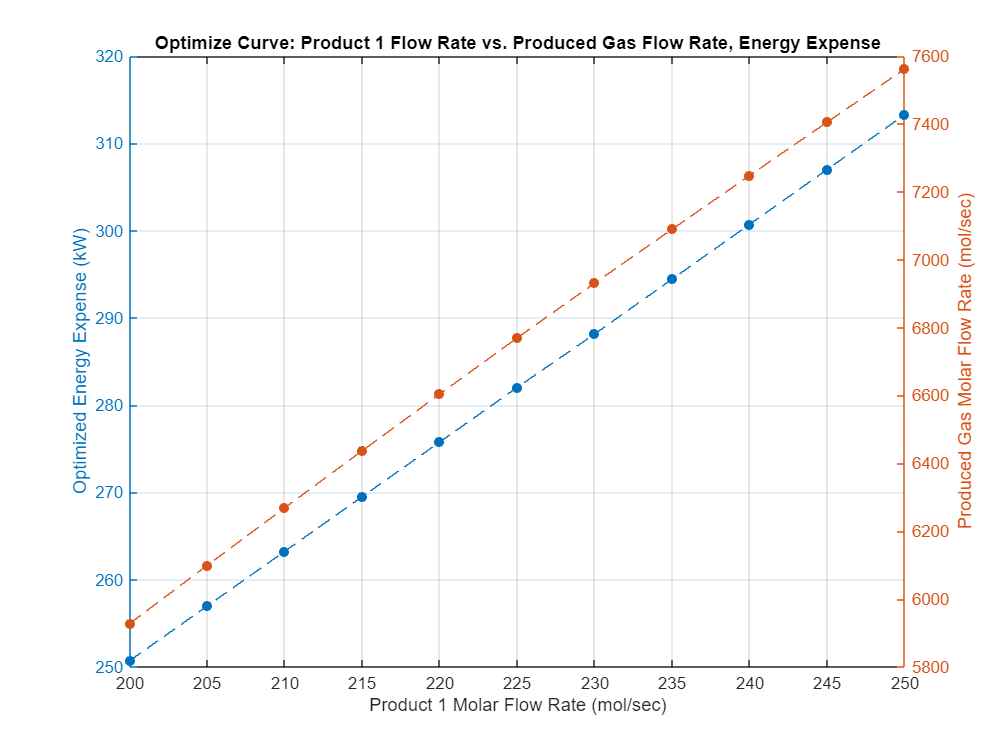


figure('Position', [100, 100, 800, 600])
hold on
yyaxis left
scatter(product1Flows,proGasRate,'filled')  
plot(product1Flows,proGasRate,'--')   
ylabel('Optimized Energy Expense (kW)')
yyaxis right
scatter(product1Flows,energyExp,'filled')  
plot(product1Flows,energyExp,'--') 
ylabel('Produced Gas Molar Flow Rate (mol/sec)')
xlabel('Product 1 Molar Flow Rate (mol/sec)')
title('Optimize Curve: Product 1 Flow Rate vs. Produced Gas Flow Rate, Energy Expense')
box on 
grid on

### Example 3: Feasibility Study

In the final example, the user can define the operational molar fraction constraints ($$ \text{MF}_i
.$$). However, some combinations of produced gas properties and operational constraints might be infeasible. Therefore, we perform a feasibility check before starting the optimization. This check ensures that the constraints can be met within the possible operational settings. If the constraints are feasible, the optimization proceeds in the same manner as the previous examples.


$$$\text{minimize Energy Usage } \\  \text{subject to}   \\ \text{Bottom1}_{\text{methane}}\leq \text{MF}_1, \\ \text{Bottom1}_{\text{ethane}}\leq \text{MF}_2, \\ \text{Product4}_{\text{butanes}}\leq \text{MF}_3.$$$$


The table below lists the decision and fixed variables of this optimization problem. For a discussion of the differences between decision and fixed variables, refer to Surrogate Model-Based Optimization. 

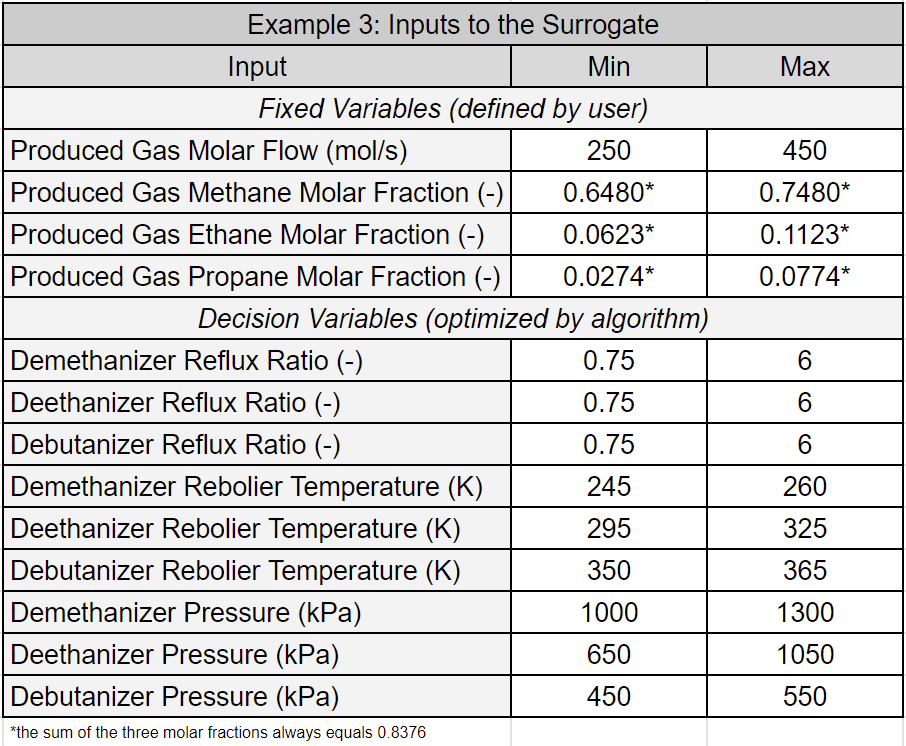

The table below outlines the range of constraints. It's important to note that using a physics-based approach to prove the feasibility of an optimization problem can be computationally expensive, as the feasibility test requires numerous function evaluations (model executions). In contrast, a surrogate-based approach can quickly assess feasibility.

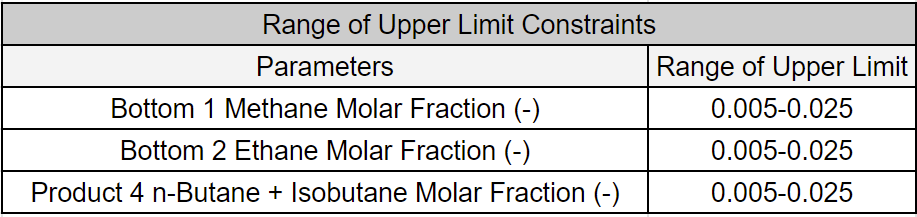

disp("Define Fixed Variables:")

Define Fixed Variables:


producedGasMolarflow = 421.1035;
producedGasEthaneFrac = 0.1025;
producedGasPropaneFrac = 0.0277;
producedGasMethaneFrac = 0.8376 - producedGasEthaneFrac - producedGasPropaneFrac;
disp("Define Molar Fractions Upper Limits:")

Define Molar Fractions Upper Limits:


bottom1_methane_limit = 0.0225;
bottom2_ethane_limit = 0.0225;
product4_butane_limit = 0.0225;

systemParameter.producedGasMolarflow = producedGasMolarflow; % [250,450]
systemParameter.producedGasEthane = producedGasEthaneFrac; %[0.0623,0.1123];
systemParameter.producedGasPropane = producedGasPropaneFrac; %[0.0274,0.0774];
systemParameter.producedGasMethane = producedGasMethaneFrac;
C = [bottom1_methane_limit, bottom2_ethane_limit, product4_butane_limit];
disp("Optimization Options:")

Optimization Options:


numFeasAttempts = 50;
numAttempts = 10;
disp(" ")

 

addpath("Surrogate Model\")
addpath("Optimization\")
addpath("Model\")

tic
disp("Checking Feasibility:")

Checking Feasibility:


for idx = 1:floor(numFeasAttempts/10)
    [feasibleFlag]  = example3_feasibility(systemParameter,10,C);
    if feasibleFlag
        break
    end
    disp(['Feasibility has not be proven in ' num2str(idx*10) ' of 100 attempts.'])
end
if feasibleFlag
    disp("Optimization Problem is Feasible!")
    [xOpt, energyExpense, constraintFlag, constraintResults, funEvals, exitFlag]  = example3_optimization(systemParameter,numAttempts,C);
    timeElasped = toc;
    if exitFlag
        disp(" ")
        disp("Optimization Problem Solved!")
        disp(" ")
        disp("Fixed Variables:")
        disp(['Produced Gas Molar Flow (mol/sec): ' num2str(producedGasMolarflow,'%.0f')])
        disp(['Ethane Molar Fraction (-): ' num2str(producedGasEthaneFrac,'%.2f')])
        disp(['Propane Molar Fraction (-): ' num2str(producedGasPropaneFrac,'%.2f')])
        disp(['Methane Molar Fraction (-): ' num2str(producedGasMethaneFrac,'%.2f')])
        disp(" ")
        disp(['Optimal Total Energy Usage (kW): ' num2str(energyExpense(1),'%.2f')])
        disp(['Condenser 1 Duty (kW): ' num2str(energyExpense(2),'%.2f')])
        disp(['Condenser 2 Duty (kW): ' num2str(energyExpense(3),'%.2f')])
        disp(['Condenser 3 Duty (kW): ' num2str(energyExpense(4),'%.2f')])
        disp(['Reboiler 1 Duty (kW): ' num2str(energyExpense(5),'%.2f')])
        disp(['Reboiler 1 Duty (kW): ' num2str(energyExpense(6),'%.2f')])
        disp(['Reboiler 1 Duty (kW): ' num2str(energyExpense(7),'%.2f')])
        disp(['Compressor Duty (kW): ' num2str(energyExpense(8),'%.2f')])
        disp(['Cooler Duty (kW): ' num2str(energyExpense(9),'%.2f')])
        disp(['Heater Duty (kW): ' num2str(energyExpense(10),'%.2f')])
        disp(" ")
        disp("Optimal Operational Settings:")
        disp(['Demethanizer Reflux Ratio (-): ' num2str(xOpt(1),'%.2f')])
        disp(['Deethanizer Reflux Ratio (-): ' num2str(xOpt(2),'%.2f')])
        disp(['Debutanizer Reflux Ratio (-): ' num2str(xOpt(3),'%.2f')])
        disp(['Demethanizer Reboiler Temperature (K): ' num2str(xOpt(4),'%.2f')])
        disp(['Deethanizer Reboiler Temperature (K): ' num2str(xOpt(5),'%.2f')])
        disp(['Debutanizer Reboiler Temperature (K): ' num2str(xOpt(6),'%.2f')])
        disp(['Demethanizer Top_pressure (kPa): ' num2str(xOpt(7)/1000,'%.0f')])
        disp(['Deethanizer  Top_pressure (kPa): ' num2str(xOpt(8)/1000,'%.0f')])
        disp(['Debutanizer  Top_pressure (kPa): ' num2str(xOpt(9)/1000,'%.0f')])
        disp(" ")
        disp("Constraints:")
        disp(['Bottom 1 Methane Molar Fraction (-): ' num2str(constraintResults(1),'%.4f')])
        disp(['Bottom 2 Ethane Molar Fraction (-): ' num2str(constraintResults(2),'%.4f')])
        disp(['Product 4 Butanes Molar Fraction (-): ' num2str(constraintResults(3),'%.4f')])
        disp(" ")
        disp("Optimization Performance:")
        disp(['Number of Optimization Attempts: ' num2str(round(numAttempts))])
        disp(['Total Number of Function Evaluations: ' num2str(funEvals)])
        disp(['Total Surrogate Model-Based Optimization Time (sec) (including feasibility check): ' num2str(timeElasped,'%.2f')])
        disp(['Predicted Total Physics-Based Optimization Time (sec) (not including feasibility check): ' num2str(funEvals*4.9570,'%.2f')])
    else
        disp("Error with optimization! Please retry.")
    end
else
    disp("Not feasible!")
end

Optimization Problem is Feasible!


Optimization Problem Solved!


Fixed Variables:


Produced Gas Molar Flow (mol/sec): 421


Ethane Molar Fraction (-): 0.10


Propane Molar Fraction (-): 0.03


Methane Molar Fraction (-): 0.71


Optimal Total Energy Usage (kW): 102374.18


Condenser 1 Duty (kW): 3858.53


Condenser 2 Duty (kW): 411.72


Condenser 3 Duty (kW): 916.51


Reboiler 1 Duty (kW): 499.78


Reboiler 1 Duty (kW): 1141.23


Reboiler 1 Duty (kW): 889.74


Compressor Duty (kW): 29.38


Cooler Duty (kW): 1360.38


Heater Duty (kW): 1130.15


Optimal Operational Settings:


Demethanizer Reflux Ratio (-): 0.75


Deethanizer Reflux Ratio (-): 0.75


Debutanizer Reflux Ratio (-): 0.75


Demethanizer Reboiler Temperature (K): 246.84


Deethanizer Reboiler Temperature (K): 308.73


Debutanizer Reboiler Temperature (K): 364.69


Demethanizer Top_pressure (kPa): 1000


Deethanizer  Top_pressure (kPa): 730


Debutanizer  Top_pressure (kPa): 550


Constraints:


Bottom 1 Methane Molar Fraction (-): 0.0225


Bottom 2 Ethane Molar Fraction (-): 0.0151


Product 4 Butanes Molar Fraction (-): 0.0182


Optimization Performance:


Number of Optimization Attempts: 10


Total Number of Function Evaluations: 786


Total Surrogate Model-Based Optimization Time (sec) (including feasibility check): 2.21


Predicted Total Physics-Based Optimization Time (sec) (not including feasibility check): 3896.20


## Summary

The DWSIM surrogate model-based optimization framework offers a robust and efficient solution for complex engineering problems. Using the speed and flexibility of surrogate models significantly reduces computational time compared to traditional physics-based methods. The optimization examples highlight its capability to meet strict production constraints and minimize energy usage. This innovative approach allows for deeper insights and rapid optimization, enhancing system performance and operational efficiency. Additionally, complex workflows such as Parameter Estimation via Profile Likelihoods and Anomaly Detection can be applied within the context of DWSIM. 

## References

- [DWSIM Homepage](https://dwsim.org/)